# **The heat equation**

## 1. Introduction

- Let's assume a 1-dimensional rod with length $L>0$ made of an isotropic material,

- The function $T(x,t)$ describes the heat of a point $x$ at time $t$, $x \in [ 0,L ]$, $t \in [0,\infty)$,

- At $t=0$, the rod has some initial heat distribution $T(x,0) = \phi(x)$,

- We assume no heat exchange with the enviornment.

Knowing that, is there a way to know how the heat distribution in the object changes over time? 

## 2. Joseph Fourier's study of heat flow

        *The Analytical Theory of Heat *(fr. *Théorie analytique de la chaleur*) is Fourier's 1822 publication of his work on heat flow. His work was based on Isaac Newton's law of cooling, which states:

*The rate of heat **loss of a body is directly proportional to the difference in the** temperatures **between the body and its environment.*

It is in this book where he famously stated, that any function can be expressed as an infinite sum of sine waves, which led to the invention of the fourier series and later, the fourier transform.


$$\frac{\partial T}{\partial t} = \alpha \cdot \frac{\partial^2 T}{\partial x^2$$


The heat equation for 1 dimension


$$\frac{\partial T}{\partial t} = \alpha \cdot \left( \frac{\partial^2 T}{\partial x^2}+\frac{\partial^2 T}{\partial y^2}+\frac{\partial^2 T}{\partial z^2} \right)$$


Let's first look at an example initial distribution $\phi (x)$

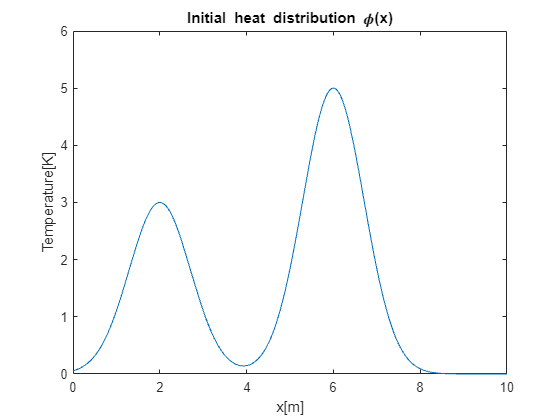

length = 10;
first_peak_middle =2;
second_peak_middle = 6;
first_peak_value = 3;
second_peak_value = 5;
syms x phi(x)
assume(x,"positive")
phi(x) = first_peak_value*exp(-(x-first_peak_middle).^2)+second_peak_value*exp(-(x-second_peak_middle).^2);

figure(1)
grid on
fplot(phi, [0 length]);
xlim([0 length])
ylim([0 max(double(subs(phi,x,first_peak_middle)),double(subs(phi,x,second_peak_middle)))+1])
title("Initial heat distribution \phi(x)")
xlabel("x[m]")
ylabel("Temperature[K]")

## 2. Solving the problem

        We know, that heat will flow from hot to cold, until it reaches a stable equilibrium. 